clc;
clear;

T1 = readtable('/Users/raaj/Desktop/IMES/G1_Dataset/G1_case11.xls', 'Sheet', 1, 'Range', 'A:E');

T2 = readtable('/Users/raaj/Desktop/IMES/G2_Dataset/G2_CASE21.xls', 'Sheet', 1, 'Range', 'A:E');

T3 = readtable('/Users/raaj/Desktop/IMES/G3_Dataset/G3_case31.xls', 'Sheet', 1, 'Range', 'A:E');

T4 = readtable('/Users/raaj/Desktop/IMES/G4_Dataset/G4_case41.xls', 'Sheet', 1, 'Range', 'A:E');

T5 = readtable('/Users/raaj/Desktop/IMES/G5_Dataset/G5_case51.xls', 'Sheet', 1, 'Range', 'A:E');

T6 = readtable('/Users/raaj/Desktop/IMES/G6_Dataset/G6_case61.xls', 'Sheet', 1, 'Range', 'A:E');

T7 = readtable('/Users/raaj/Desktop/IMES/G7_Dataset/G7_case71.xls', 'Sheet', 1, 'Range', 'A:E');

T8 = readtable('/Users/raaj/Desktop/IMES/G8_Dataset/G8_case81.xlsx', 'Sheet', 1, 'Range', 'A:E');

T9 = readtable('/Users/raaj/Desktop/IMES/G9_Dataset/G9_case91.xls', 'Sheet', 1, 'Range', 'A:E');

save('T1','T2',"T3","T4","T5","T6","T7","T8","T9")

% checking T1
disp('Table Data:')

Table Data:


disp(T1)

    Time_s_    LinearAccelerationX_m_s_2_    LinearAccelerationY_m_s_2_    LinearAccelerationZ_m_s_2_    AbsoluteAcceleration_m_s_2_
    _______    __________________________    __________________________    __________________________    ___________________________

    0.11803              0.044338                     -0.011587                        0.3078                       0.31119         
    0.12057              0.070288                    -0.0046874                        0.3228                        0.3304         
     0.1231              0.034288                     -0.047587                       0.31575                       0.32115         
    0.12564              0.046288                      0.031313                        0.2727                       0.27837         
    0.12818              0.0415

data1 = table2array(T1);
data2 = table2array(T2);
data3 = table2array(T3);
data4 = table2array(T4);
data5 = table2array(T5);
data6 = table2array(T6);
data7 = table2array(T7);
data8 = table2array(T8);
data9 = table2array(T9);
disp(data1)

    0.1180    0.0443   -0.0116    0.3078    0.3112
    0.1206    0.0703   -0.0047    0.3228    0.3304
    0.1231    0.0343   -0.0476    0.3157    0.3211
    0.1256    0.0463    0.0313    0.2727    0.2784
    0.1282    0.0415    0.0189    0.2577    0.2617
    0.1307    0.0175   -0.0531    0.2457    0.2519
    0.1333    0.0514   -0.0441    0.2727    0.2809
    0.1358    0.0465   -0.0510    0.2727    0.2813
    0.1383    0.0397   -0.0225    0.2797    0.2834
    0.1409    0.0517    0.0086    0.2486    0.2541
    0.1434    0.0468    0.0035    0.2287    0.2334
    0.1460    0.0418    0.0086    0.2437    0.2474
    0.1485    0.0448   -0.0089    0.2627    0.2666
    0.1510    0.0277   -0.0089    0.2916    0.2931
    0.1536    0.0637   -0.0469    0.3227    0.3322
    0.1561    0.0568    0.0031    0.2726    0.2785
    0.1586    0.0247   -0.0452    0.2696    0.2745
    0.1612    0.0487   -0.0332    0.2987    0.3044
    0.1637    0.0688   -0.0281    0.2747    0.2846
    0.1663    0.0328   -0.0640 

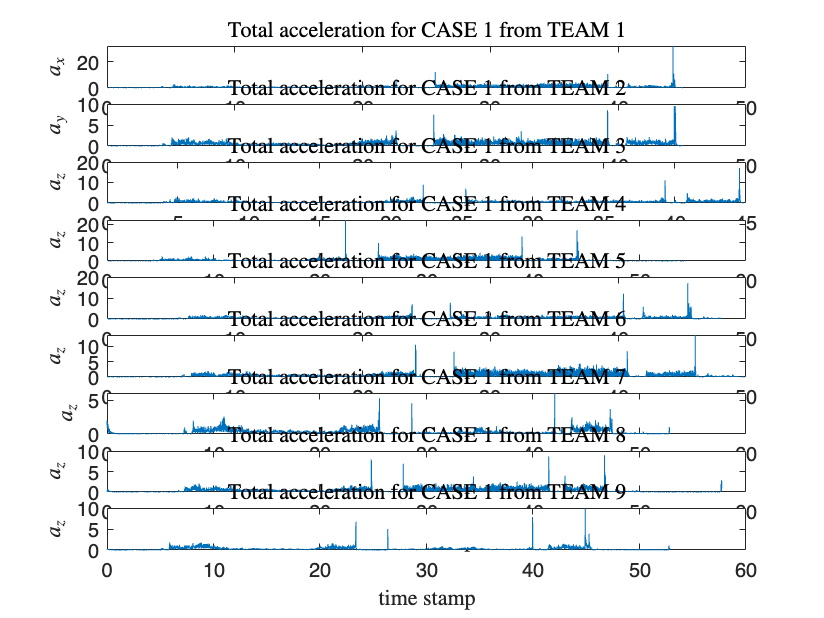

figure;

% subplot(row, column, index of current figure)
subplot(9, 1, 1); % the 1st subplot
y1 = data1(:,5);
plot(data1(:,1), y1); 
title('Total acceleration for CASE 1 from TEAM 1', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_x$$', 'Interpreter', 'latex');

subplot(9, 1, 2); % the 2nd subplot
y2 = data2(:,5);
plot(data2(:,1), y2);
title('Total acceleration for CASE 1 from TEAM 2', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_y$$', 'Interpreter', 'latex');

subplot(9, 1, 3); % the 3rd subplot
y3 = data3(:,5);
plot(data3(:,1), y3);
title('Total acceleration for CASE 1 from TEAM 3', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_z$$', 'Interpreter', 'latex');

subplot(9, 1, 4); % the 4rd subplot
y4 = data4(:,5);
plot(data4(:,1), y4);
title('Total acceleration for CASE 1 from TEAM 4', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_z$$', 'Interpreter', 'latex');

subplot(9, 1, 5); % the 5th subplot
y5 = data5(:,5);
plot(data5(:,1), y5);
title('Total acceleration for CASE 1 from TEAM 5', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_z$$', 'Interpreter', 'latex');

subplot(9, 1, 6); % the 6th subplot
y6 = data6(:,5);
plot(data6(:,1), y6);
title('Total acceleration for CASE 1 from TEAM 6', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_z$$', 'Interpreter', 'latex');

subplot(9, 1, 7); % the 7th subplot
y7 = data7(:,5);
plot(data7(:,1), y7);
title('Total acceleration for CASE 1 from TEAM 7', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_z$$', 'Interpreter', 'latex');

subplot(9, 1, 8); % the 8th subplot
y8 = data8(:,5);
plot(data8(:,1), y8);
title('Total acceleration for CASE 1 from TEAM 8', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_z$$', 'Interpreter', 'latex');

subplot(9, 1, 9); % the 9th subplot
y9 = data9(:,5);
plot(data9(:,1), y9);
title('Total acceleration for CASE 1 from TEAM 9', 'Interpreter', 'latex');
xlabel('time stamp', 'Interpreter', 'latex');
ylabel('$$a_z$$', 'Interpreter', 'latex');